load('playpensample.mat');
theta = theta(r>0);
r = r(r>0);
theta = theta(r<5);
r = r(r<5);
[x,y] = pol2cart(deg2rad(theta),r);
xOrig = x;
yOrig = y;



bucketRad = 0.1143;
starts = [];
vects = [];
buckets = [];
minErr = Inf;
bucket = 0;
i=1;
while(length(x)>2)
    %plot(x,y,'bs')
    figure
    [bestStart,bestVect,ptsOnLine] = findLine(x, y, .01, 100);
    if(sum(ptsOnLine)<5)
        x = x(~ptsOnLine);
        y = y(~ptsOnLine);  
        continue
    end
    [cent, r, err] = getCircle(x(ptsOnLine),y(ptsOnLine));
    if(abs(r-bucketRad)<.05 && err<1)
        buckets = [buckets 1];
        r
        err
        if err<minErr
            bucket = i;
            minErr = err;
        end
    else
        buckets = [buckets 0];
    end
    starts = [starts bestStart];
    vects = [vects bestVect];
    x = x(~ptsOnLine);
    y = y(~ptsOnLine);  
    i=i+1;
end

r = 0.1329

err = 0.7960

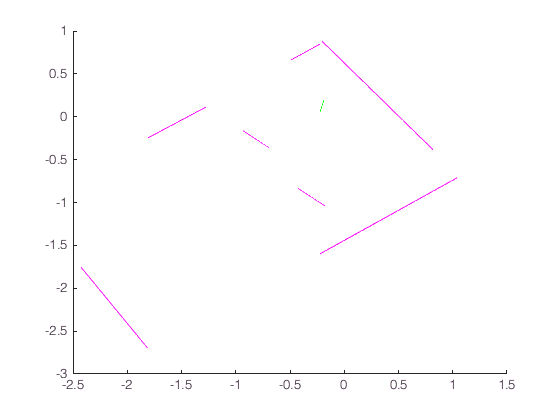

clf
%plot(xOrig,yOrig, 'ks');
hold on
t = linspace(0, 1);
for i = 1:size(vects,2)
    if ~buckets(i)
        plot(t*vects(1,i)+starts(1,i),t*vects(2,i)+starts(2,i),'m');
    else
        if i==bucket
            plot(t*vects(1,i)+starts(1,i),t*vects(2,i)+starts(2,i),'g');
        else
            plot(t*vects(1,i)+starts(1,i),t*vects(2,i)+starts(2,i),'b');
        end
    end
end

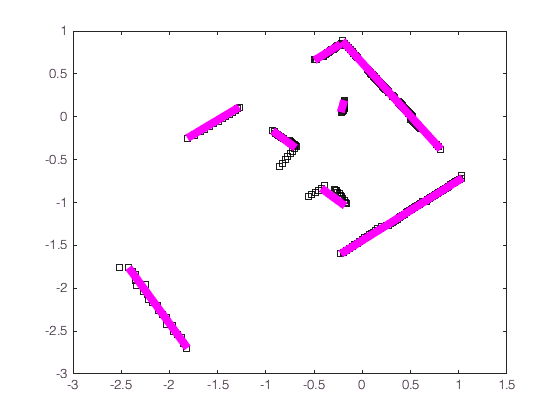

figure
clf
plot(xOrig,yOrig, 'ks');
hold on
t = linspace(0, 1);
for i = 1:size(vects,2)
    plot(t*vects(1,i)+starts(1,i),t*vects(2,i)+starts(2,i),'m','LineWidth', 6);
end

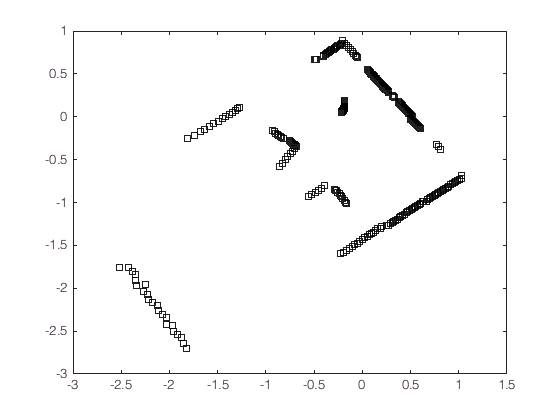

figure
plot(xOrig,yOrig, 'ks');

function res = dist2line(x, y, start, vect)
    M = [x y];
    M = M - start';
    normal = [-vect(2) ; vect(1)];
    normal = normal/norm(normal);
    res = abs(M * normal);
end
function res = distOnLine(x, y, start, vect)
    M = [x y];
    M = M - start';
    projVect = vect/norm(vect);
    res = M * projVect;
end
function [bestStart,bestVect,ptsOnLine] = findLine(x, y, epsilon, nTries)
    nPoints = length(x);

    bestStart = [0; 0];
    bestVect = [0; 0];
    bestScore = -Inf;
    ptsOnLine = [];
    
    for succ = 1:nTries
        i=0;
        j=0;
        while(i==j)
            i = randi(nPoints);
            j = randi(nPoints);
        end
        a = [x(i);y(i)];
        b = [x(j);y(j)];
        vect = b-a;
        dist = dist2line(x,y,a,vect);
        score = sum(dist < epsilon);
        if(score > bestScore)
            bestScore = score;
            bestStart = a;
            bestVect = vect;
            ptsOnLine = dist < epsilon;
        end
    end
    ptsOnLine = removeGaps(x, y, ptsOnLine, bestStart, bestVect, .3);
    [bestStart, bestVect] = linRegPCA(x(ptsOnLine), y(ptsOnLine));
end
function pts = removeGaps(x, y, ptsOnLine, start, vect, epsilon)
    xsOnLine = x(ptsOnLine);
    ysOnLine = y(ptsOnLine); 
    ts = distOnLine(xsOnLine, ysOnLine, start, vect/norm(vect));
    [tsSorted,indicies] = sort(ts);
    diffs = diff(tsSorted);
    meanDiff = mean(diffs);
    breaks = [0; find(diffs>epsilon); length(ts)];
    lengths = diff(breaks);
    [~,maxSegment] = max(lengths);
    indiciesOnLine = breaks(maxSegment)+1:breaks(maxSegment+1);
    localIndicies = indicies(indiciesOnLine);
    
    L = [xsOnLine(localIndicies) ysOnLine(localIndicies)];
    G = [x y];
    
    pts = ismember(G, L, 'rows');
end
function [cent,r,err] = getCircle(x, y)
    nPoints = length(x);
    A = [x y ones(nPoints,1)];
    b = -x.^2-y.^2;
    w = A\b;
    cent = [-w(1)/2 -w(2)/2];
    r = sqrt(cent(1)^2 + cent(2)^2 -w(3));
    
    M = [x y] - cent;
    r_actual = sqrt(diag(A*A'));
    err = mean((r_actual-r).^2);
end
function [mu,v] = linRegPCA(x,y)
    XY = [x y];
    A = XY;
    mu = mean(A);
    A = A - mu;
    mu = mu';
    [~, ~, V] = svd(A,'econ');
    v = V(:,1);
    ts = distOnLine(x, y, mu, v);
    [tmin,minIndex] = min(ts);
    tmax = max(ts);
    mu = XY(minIndex,:)';
    len = tmax-tmin;
    v = v * len;
end